# Progetto 

## dati

clear; clc; close all;

E=210*10^9;
rho=7800;   ni=0.3;
h1=1*10^-6;    h2=1.2*10^-6;
lx=1.7*10^-4;  lcs=1.3*10^-4;
ly=0.9*10^-4;    lz=0.6*10^-4;
xhat=1.1*10^-4;   yhat=0.5*10^-4;
cshat=1*10^-4;   zhat=0.2*10^-4;
D1=E*h1^3/(12*(1-ni^2)); D2=E*h2^3/(12*(1-ni^2));
m1=rho*h1*lx*ly;
m2=rho*h2*lcs*lz; massa=[m1,m2];
PHI=zeros(5,1);
PHI_tilde=zeros(5,1);
LAMBDA=zeros(10,10);


## K

cont=0;
nmax=5; mmax=5;
for n=1:nmax
    for m=1:mmax
        cont=cont+1;
        om1(cont)=sqrt(D1/rho/h1)*((n*pi/lx)^2+(m*pi/ly)^2);
        array1(n,m)=cont;
        n_modi1(cont,1)=n;
        n_modi1(cont,2)=m;
    end
end
[om_1,I1]=sort(om1);
om_1(1:5)=om_1(1:5)

om_1 = 	1.0e+07 *

    0.2449    0.4058    0.6739    0.8189    0.9798    1.0493    1.2479    1.5319    1.6233    1.7755    1.9364    2.1059    2.2045    2.5799    3.0625    3.1148    3.2757    3.5438    3.9191    4.4017    4.8367    4.9976    5.2657    5.6410    6.1236


cont2=0;
for n=1:nmax
    for m=1:mmax
        cont2=cont2+1;
        om2(cont2)=sqrt(D2/rho/h2)*((n*pi/lcs)^2+(m*pi/lz)^2);
        array2(n,m)=cont2;
        n_modi2(cont2,1)=n;
        n_modi2(cont2,2)=m;
    end
end
[om_2,I2]=sort(om2);
om_2(1:5)=om_2(1:5)

om_2 = 	1.0e+08 *

    0.0627    0.0957    0.1507    0.2176    0.2277    0.2506    0.3057    0.3268    0.3827    0.4759    0.4817    0.5089    0.5639    0.6410    0.7400    0.8375    0.8705    0.9255    1.0026    1.1016    1.3024    1.3354    1.3905    1.4675    1.5665



[om_min,piastra]=min([om_1,om_2])

om_min = 2.4495e+06

piastra = 1

if piastra>nmax
    piastra=2;
else
    piastra=1;
end
k=0.1*(2*pi*om_min)^2*massa(piastra,1)

k = 2.8267e+03

C1=4*k/(lx*ly*rho*h1);
C2=4*k/(lcs*lz*rho*h2);

## modi e equazione di bilancio

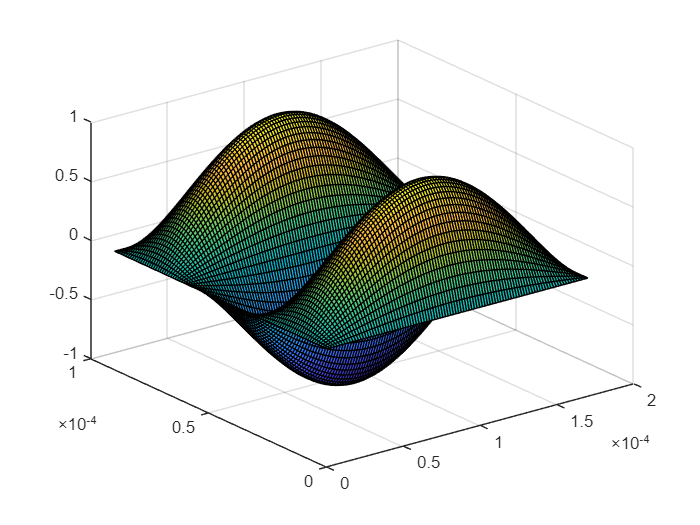

dx=0.1*10^-4; x=linspace(0,lx,100); Nx=length(x);
dy=dx/2; y=linspace(0,ly,100); Ny=length(y);
dcs=dx; cs=dcs:dcs:lcs-dcs; Ncs=length(cs);
dz=1/2*dx; z=dz:dz:lz-dz; Nz=length(z);
for ix=1:Nx
    for iy=1:Ny
        for r=1:5
            phi1(ix,iy,r)= sin((n_modi1(I1(r),1)*x(ix)*pi/lx))*sin(n_modi1(I1(r),2)*y(iy)*pi/ly);
        end
    end
end

[X,Y]=meshgrid(x,y);

surf(X,Y,phi1(:,:,3));

## Costruzione PHI nei punti noti

for i=1:nmax
Phi(i,1)=sin(n_modi1(I1(i),1)*xhat/lx)*sin(n_modi1(I1(i),2)*yhat/ly)
end

Phi = 0.3179

Phi =     0.3179
    0.5074


Phi =     0.3179
    0.5074
    0.4917


Phi =     0.3179
    0.5074
    0.4917
    0.5403


Phi =     0.3179
    0.5074
    0.4917
    0.5403
    0.8621


for k=1:nmax
Phi_tilde(k,1)=sin(n_modi2(I2(k),1)*cshat/lcs)*sin(n_modi2(I2(k),2)*zhat/lz)
end

Phi_tilde = 0.2276

Phi_tilde =     0.2276
    0.3270


Phi_tilde =     0.2276
    0.3270
    0.2423


Phi_tilde =     0.2276
    0.3270
    0.2423
    0.4301


Phi_tilde =     0.2276
    0.3270
    0.2423
    0.4301
    0.0211


PHI=[ C1*Phi*Phi' , -C1*Phi*Phi_tilde'; -C2*Phi_tilde*Phi' C2*Phi_tilde*Phi_tilde'] 

PHI = 	1.0e+13 *

    0.9578    1.5284    1.4811    1.6275    2.5970   -0.6856   -0.9851   -0.7299   -1.2957   -0.0637
    1.5284    2.4389    2.3634    2.5970    4.1441   -1.0940   -1.5720   -1.1648   -2.0676   -0.1016
    1.4811    2.3634    2.2902    2.5166    4.0159   -1.0602   -1.5233   -1.1287   -2.0036   -0.0985
    1.6275    2.5970    2.5166    2.7655    4.4129   -1.1650   -1.6740   -1.2403   -2.2017   -0.1082
    2.5970    4.1441    4.0159    4.4129    7.0418   -1.8590   -2.6712   -1.9792   -3.5133   -0.1727
   -1.1207   -1.7883   -1.7330   -1.9043   -3.0387    0.8022    1.1527    0.8541    1.5161    0.0745
   -1.6103   -2.5696   -2.4901   -2.7363   -4.3663    1.1527    1.6563    1.2272    2.1785    0.1071
   -1.1932   -1.9039   -1.8450   -2.0274   -3.2352    0.8541    1.2272    0.9093    1.6141    0.0793
   -2.1180   -3.3798   -3.2751   -3.5990   -5.7429    1.5161    2.1785    1.6141    2.8653    0.1409
   -0.1041   -0.1661   -0.1610   -0.1769   -0.2823    0.0745    0.1071   

LAMBDA=[diag(om_1(1:5)).^2 zeros(nmax);  zeros(nmax) diag(om_2(1:5)).^2]

LAMBDA = 	1.0e+14 *

    0.0600         0         0         0         0         0         0         0         0         0
         0    0.1647         0         0         0         0         0         0         0         0
         0         0    0.4542         0         0         0         0         0         0         0
         0         0         0    0.6706         0         0         0         0         0         0
         0         0         0         0    0.9600         0         0         0         0         0
         0         0         0         0         0    0.3926         0         0         0         0
         0         0         0         0         0         0    0.9153         0         0         0
         0         0         0         0         0         0         0    2.2708         0         0
         0         0         0         0         0         0         0         0    4.7364         0
         0         0         0         0         0         0         0

LAMBDA_tilde=LAMBDA+PHI

LAMBDA_tilde = 	1.0e+14 *

    0.1558    0.1528    0.1481    0.1627    0.2597   -0.0686   -0.0985   -0.0730   -0.1296   -0.0064
    0.1528    0.4086    0.2363    0.2597    0.4144   -0.1094   -0.1572   -0.1165   -0.2068   -0.0102
    0.1481    0.2363    0.6832    0.2517    0.4016   -0.1060   -0.1523   -0.1129   -0.2004   -0.0098
    0.1627    0.2597    0.2517    0.9472    0.4413   -0.1165   -0.1674   -0.1240   -0.2202   -0.0108
    0.2597    0.4144    0.4016    0.4413    1.6642   -0.1859   -0.2671   -0.1979   -0.3513   -0.0173
   -0.1121   -0.1788   -0.1733   -0.1904   -0.3039    0.4729    0.1153    0.0854    0.1516    0.0075
   -0.1610   -0.2570   -0.2490   -0.2736   -0.4366    0.1153    1.0810    0.1227    0.2178    0.0107
   -0.1193   -0.1904   -0.1845   -0.2027   -0.3235    0.0854    0.1227    2.3617    0.1614    0.0079
   -0.2118   -0.3380   -0.3275   -0.3599   -0.5743    0.1516    0.2178    0.1614    5.0229    0.0141
   -0.0104   -0.0166   -0.0161   -0.0177   -0.0282    0.0075    

[PHI_tot,om_tot]=eig(LAMBDA_tilde)

PHI_tot =    -0.0398    0.0142   -0.0954   -0.0888   -0.9577   -0.0057   -0.0504    0.2098   -0.0750   -0.0270
   -0.0648    0.0231   -0.1586   -0.1498    0.2668   -0.0103   -0.0949    0.8900   -0.1548   -0.0620
   -0.0666    0.0238   -0.1737   -0.1725    0.0609   -0.0161   -0.1840   -0.2405   -0.8064    0.2871
   -0.0766    0.0274   -0.2115   -0.2207    0.0426   -0.0328   -0.7995   -0.1351    0.3904    0.0593
   -0.1306    0.0467   -0.3944   -0.4510    0.0457    0.3711    0.4324   -0.1304    0.2129    0.0454
    0.0498   -0.0178    0.1279    0.1255   -0.0550    0.0108    0.1148    0.2500    0.3162    0.9521
    0.0801   -0.0287    0.2384    0.2680   -0.0298    0.9277   -0.3379    0.0861   -0.1469   -0.0306
    0.0864   -0.0312    0.7683   -0.7623   -0.0085   -0.0045   -0.0281    0.0215   -0.0246   -0.0062
    0.8978   -0.3647   -0.2677   -0.1381   -0.0071   -0.0028   -0.0191    0.0173   -0.0181   -0.0047
    0.3802    0.9277   -0.0108   -0.0058   -0.0003   -0.0001   -0.0008    0.0008 

om_tot = 	1.0e+14 *

    5.2446         0         0         0         0         0         0         0         0         0
         0    5.1771         0         0         0         0         0         0         0         0
         0         0    2.6754         0         0         0         0         0         0         0
         0         0         0    1.9907         0         0         0         0         0         0
         0         0         0         0    0.0756         0         0         0         0         0
         0         0         0         0         0    0.9242         0         0         0         0
         0         0         0         0         0         0    0.7439         0         0         0
         0         0         0         0         0         0         0    0.2278         0         0
         0         0         0         0         0         0         0         0    0.5204         0
         0         0         0         0         0         0         0

omtot=diag(om_tot)

omtot = 	1.0e+14 *

    5.2446
    5.1771
    2.6754
    1.9907
    0.0756
    0.9242
    0.7439
    0.2278
    0.5204
    0.4041


[omtot,Itot]=sort(omtot)  %nuove frequenze del sistema accoppiato   Itot=colonna di PHI_tot

omtot = 	1.0e+14 *

    0.0756
    0.2278
    0.4041
    0.5204
    0.7439
    0.9242
    1.9907
    2.6754
    5.1771
    5.2446


Itot =      5
     8
    10
     9
     7
     6
     4
     3
     2
     1


omtot=omtot(1:5)

omtot = 	1.0e+13 *

    0.7556
    2.2782
    4.0407
    5.2037
    7.4386


C=[2*0.05*diag(omtot)]

C = 	1.0e+12 *

    0.7556         0         0         0         0
         0    2.2782         0         0         0
         0         0    4.0407         0         0
         0         0         0    5.2037         0
         0         0         0         0    7.4386
